## [Proportional Integral (PI) Control](https://apmonitor.com/pdc/index.php/Main/ProportionalIntegralControl)

A variation of Proportional Integral Derivative (PID) control is to use only the proportional and integral terms as PI control. The PI controller is the most popular variation, even more than full PID controllers. The value of the controller output u(t) is fed into the system as the manipulated variable input.


$$e(t) = SP-PV$$



$$u(t) = u_{bias} + K_c \, e(t) + \frac{K_c}{\tau_I}\int_0^t e(t)dt$$


The $u_{bias}$ term is a constant that is typically set to the value of $u(t)$ when the controller is first switched from manual to automatic mode. This gives "bumpless" transfer if the error is zero when the controller is turned on. The two tuning values for a PI controller are the controller gain, $K_c$ and the integral time constant $\tau_I$. The value of $K_c$ is a multiplier on the proportional error and integral term and a higher value makes the controller more aggressive at responding to errors away from the set point. The set point (*SP*) is the target value and process variable (*PV*) is the measured value that may deviate from the desired value. The error from the set point is the difference between the *SP* and *PV* and is defined as $e(t) = SP - PV$.

## Discrete PI Controller

Digital controllers are implemented with discrete sampling periods and a discrete form of the PI equation is needed to approximate the integral of the error. This modification replaces the continuous form of the integral with a summation of the error and uses $\Delta t$ as the time between sampling instances and $n_t$ as the number of sampling instances.


$$u(t) = u_{bias} + K_c \, e(t) + \frac{K_c}{\tau_I}\sum_{i=1}^{n_t} e_i(t)\Delta t$$


## Overview of PI Control

PI control is needed for non-integrating processes, meaning any process that eventually returns to the same output given the same set of inputs and disturbances. A P-only controller is best suited to integrating processes. Integral action is used to remove offset and can be thought of as an adjustable $u_{bias}$.

Common tuning correlations for PI control are the ITAE (Integral of Time-weighted Absolute Error) method and IMC (Internal Model Control). IMC is an extension of *lambda* tuning by accounting for time delay. The parameters $K_c$, $\tau_p$, and $\theta_p$ are obtained by fitting dynamic input and output data to a first-order plus dead-time (FOPDT) model (see L6 and L7).

## IMC Tuning Correlations


$$\mathrm{Aggressive\,Tuning:} \quad \tau_c = \max \left( 0.1 \tau_p, 0.8 \theta_p \right)$$



$$\mathrm{Moderate\,Tuning:} \quad \tau_c = \max \left( 1.0 \tau_p, 8.0 \theta_p \right)$$



$$\mathrm{Conservative\,Tuning:} \quad \tau_c = \max \left( 10.0 \tau_p, 80.0 \theta_p \right)$$



$$K_c = \frac{1}{K_p}\frac{\tau_p}{\left( \theta_p + \tau_c \right)} \quad \quad \tau_I = \tau_p$$


Note that with moderate tuning and negligible dead-time $(\theta_p \rightarrow 0  \text{  and }  \tau_c = 1.0 \tau_p)$, IMC reduces to simple tuning correlations that are easy to recall without a reference book.


$$K_c = \frac{1}{K_p} \quad \quad \tau_I = \tau_p \quad \quad \mathrm{Simple\,tuning\,correlations}$$


## ITAE Tuning Correlations

Different tuning correlations are provided for disturbance rejection (also referred to as *regulatory* control) and set point tracking (also referred to as *servo* control).


$$K_c = \frac{0.586}{K_p}\left(\frac{\theta_p}{\tau_p}\right)^{-0.916} \quad \tau_I = \frac{\tau_p}{1.03-0.165\left(\theta_p/\tau_p\right)}\quad\mathrm{Set\;point\;tracking}$$



$$K_c = \frac{0.859}{K_p}\left(\frac{\theta_p}{\tau_p}\right)^{-0.977} \quad \tau_I = \frac{\tau_p}{0.674}\left(\frac{\theta_p}{\tau_p}\right)^{0.680}\quad\mathrm{Disturbance\;rejection}$$


## Anti-Reset Windup

An important feature of a controller with an integral term is to consider the case where the controller output u(t) saturates at an upper or lower bound for an extended period of time. This causes the integral term to accumulate to a large summation that causes the controller to stay at the saturation limit until the integral summation is reduced. Anti-reset windup is that the integral term does not accumulate if the controller output is saturated at an upper or lower limit.

Suppose that a driver of a vehicle set the desired speed set point to a value higher than the maximum speed. The automatic controller would saturate at full throttle and stay there until the driver lowered the set point. Suppose that the driver kept the speed set point higher than the maximum velocity of the vehicle for an hour. The discrepancy between the set point and the current speed would create a large integral term. If the driver then set the speed set point to zero, the controller would wait to lower the throttle until the negative error cancels out the positive error from the hour of driving. The automobile would not slow down but continue at full throttle for an extended period of time. This undesirable behavior is fixed by implementing anti-reset windup.

## Exercise

The purpose of this exercise is to investigate the cause of offset in a P-only controller and oscillations in a PI controller.

**Open Loop Response**

Consider a first order plus dead time process as


$$\tau_p \frac{dy}{dt} = -y + K_p u \left(t-\theta_p\right)$$


with $K_p = 2$, $\tau_p = 200$, and $\theta_p = 0$. Simulate the behavior for making a step change in manual mode from 0 to 10 (and back). Explain what happens in terms of oscillations or a smooth response.

**P-only Control**

Simulate the behavior for using a P-only controller with $K_c = 2$ and $K_c=0.5$. Implement a set point change from 0 to 10 and back in automatic mode (closed-loop). Include a plot of the error between the set point (*SP*) and process variable (*PV*). What happens with increased $K_c$ in terms of offset and oscillation?

**PI Control**

Configure the controller to add an integral term in addition to the proportional control with $K_c = 2$. Simulate the PI controller response with integral reset times $\tau_I=200, 100, 10$. Include a plot of the integral of the error between the set point (*SP*) and process variable (*PV*) with anti-reset windup. Explain what happens and why.

**Open Loop Response with Dead Time**

Add dead time $\theta_p=100$ as an input delay. Simulate the behavior for making a step change in manual mode from 0 to 10 (and back). Explain what happens in terms of oscillations.

**P-only Control with Dead Time**

With the dead time, simulate the response of a P-only controller with $K_c=2$ and $K_c=0.5$. Implement a set point change from 0 to 10 and back in automatic mode (closed-loop). Include a plot of the error between the set point (*SP*) and process variable (*PV*). What happens with increased $K_c$ in terms of offset and oscillation?

**PI Control with Dead Time**

Simulate the response of a PI controller with $\tau_I=200$. Include a plot of the integral of the error between the set point (*SP*) and process variable (*PV*) with anti-reset windup. Explain what happens and why. Explain the results.

**Summary Questions**

- Based on the observations in manual mode, is the process stable or unstable?

- Why does P-only control have persistent offset?

- What is the effect of dead time on P-only and PI control?

- If the process is stable, why can the control system make it unstable?

**Sample Code**

clc
clear

% specify number of steps
ns = 1200;
% define time points
t = linspace(0,ns,(ns+1));

% mode (manual=0, automatic=1)
mode = 1;

% process model
model(1) = 2.0; %Kp
model(2) = 200.0; %taup
model(3) = 0.0; %thetap


% PID tuning
pidparam(1) = 2.0; %Kc
pidparam(2) = 10.0; %tauI
pidparam(3) = 0; %tauD

% Define Set Point
sp = zeros(1,ns+1);  % set point
sp(50:600) = 10;
sp(600:end) = 0;

mode = 0;

y = 1; %placeholder variable
[pv,op, iopsave] = calc_response(t,y,mode,model,pidparam, sp)

     0

         0
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0001
   -0.0001
   -0.0001
   -0.0002
   -0.0002
   -0.0002
   -0.0003
   -0.0003
   -0.0004
   -0.0004
   -0.0005
   -0.0005
   -0.0006
   -0.0006
   -0.0007
   -0.0008
   -0.0008
   -0.0009
   -0.0010
   -0.0011
   -0.0011
   -0.0012
   -0.0013
   -0.0014
   -0.0015
   -0.0016
   -0.0017
   -0.0018
   -0.0019
   -0.0020
   -0.0021
   -0.0023
   -0.0024
   -0.0025

    0.0025

   -0.0025
   -0.0026
   -0.0028
   -0.0029
   -0.0030
   -0.0032
   -0.0033
   -0.0035
   -0.0036
   -0.0038
   -0.0039
   -0.0041
   -0.0042
   -0.0044
   -0.0046
   -0.0047
   -0.0049
   -0.0051
   -0.0053
   -0.0054
   -0.0056
   -0.0058
   -0.0060
   -0.0062
   -0.0064
   -0.0066
   -0.0068
   -0.0070
   -0.0072
   -0.0074
   -0.0077
   -0.0079
   -0.0081
   -0.0083
   -0.0086
   -0.0088
   -0.0090
   -0.0093
   -0.0095
   -0.0098
   -0.0100

    0.0100

   -0.0100
   -0.0103
   -0.0105
   -0.0108
   -0.0110
   -0.011

pv = 	1.0e+03 *

         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005   -0.0006   -0.0006   -0.0007   -0.0008   -0.0009   -0.0010   -0.0011   -0.0012   -0.0013   -0.0014   -0.0016   -0.0017   -0.0018   -0.0020   -0.0021   -0.0023   -0.0024   -0.0026   -0.0027   -0.0029   -0.0031   -0.0032   -0.0034   -0.0036   -0.0038   -0.0040   -0.0042   -0.0044   -0.0046   -0.0048   -0.0051   -0.0053   -0.0055   -0.0058   -0.0060


op =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


iopsave = 1×1200 int64 row vector
    1    1    2    3    4    5    6    7    8    9   10   11   12   13   14   15   16   17   18   19   20   21   22   23   24   25   26   27   28   29   30   31   32   33   34   35   36   37   38   39   40   41   42   43   44   45   46   47   48   49


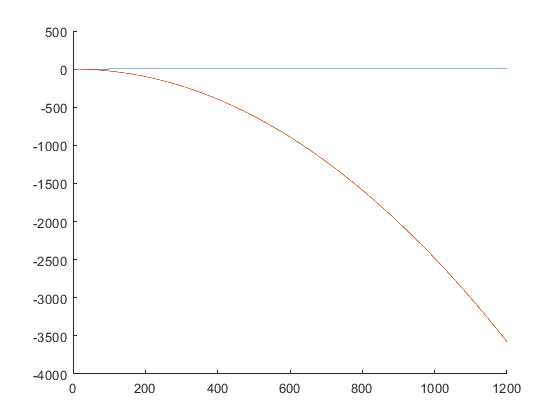

hold on
plot(t,op)
plot(t,pv)

plot(t,iopsave(1:1200))

Error using plot
Vectors must be the same length.

function dydt = process(y,t,u,Kp,taup)
    dydt = -y/taup + Kp/taup*u;
end

function [pv, op , iopsave] = calc_response(t, y, mode, xm, xc, sp)
    % t = time points
    % mode (manual=0, automatic=1)
    % process model
    Kp = xm(1);
    taup = xm(2);
    thetap = xm(3);
    % specify number of steps
    ns = length(t)-1;
    % PID tuning
    Kc = xc(1);
    tauI = xc(2);
    tauD = xc(3);


    delta_t = t(2)-t(1);

    % storage for recording values
    op  = zeros(1, ns+1);    % controller output
    pv  = zeros(1, ns+1);    % process variable
    e   = zeros(1, ns+1);    % error
    ie  = zeros(1, ns+1);    % integral of the error
    dpv = zeros(1, ns+1);    % derivative of the pv
    P   = zeros(1, ns+1);    % proportional
    I   = zeros(1, ns+1);    % integral
    D   = zeros(1, ns+1);    % derivative

    % step input for manual control
    if mode==0
        op(100:end)=2;
    end
    % Upper and Lower limits on OP
    op_hi = 100.0;
    op_lo = 0.0;

    % Simulate time delay
    ndelay = int64(ceil(thetap / delta_t));

    % loop through time steps    
    for i = 1:ns %Just do a:ns not 1:ns+1
        e(i) = sp(i) - pv(i);
      %error should start at zero and stay there for a while
      %since sp is in fact 0 pv is the problem
        %op looks good
        %y is not zero it should be zero WHY IS IT NOT ZERO?????
      disp(e(i))
        if i > 1  % calculate starting on second cycle
            dpv(i) = (pv(i)-pv(i-1))/delta_t;
            ie(i) = ie(i-1) + e(i) * delta_t;
        end
        P(i) = Kc * e(i);
        I(i) = Kc/tauI * ie(i);
        D(i) = - Kc * tauD * dpv(i);
        if mode==1
            op(i) = op(1) + P(i) + I(i) + D(i);
        end
        if op(i) > op_hi  % check upper limit
            op(i) = op_hi;
            ie(i) = ie(i) - e(i) * delta_t; % anti-reset windup
        end
        if op(i) < op_lo  % check lower limit
            op(i) = op_lo;
            ie(i) = ie(i) - e(i) * delta_t; % anti-reset windup
        end
        % implement time delay
        iop = max([1,i-ndelay-1]);
        iopsave(i)= iop;
%         y = odeint(process,pv(i),[0,delta_t],args=(op[iop],Kp,taup))
        ts = [delta_t*(i-1),delta_t*i];
        [t, y] = ode45(@(t, y) process(t,y,op(iop),Kp,taup),ts, pv(i));

        disp(y)
        pv(i+1) = y(end);
        %PV has an extra because it can't start at 0
    end
       
    op(ns) = op(ns-1);
    ie(ns) = ie(ns-1);
    P(ns) = P(ns-1);
    I(ns) = I(ns-1);
    D(ns) = D(ns-1);
end